# Signal Analysis for Protocol 2

Water level - 23.4cm

Bottom of Tub - 37cm

Peak Response- 45cm

From the plot with the depths of the amplitudes. The curves oscillate harmonically with increasing amplitude. Higher radar response the deeper the chicken is in the water. Possibility of estimating depth with just the period of the oscillaton.

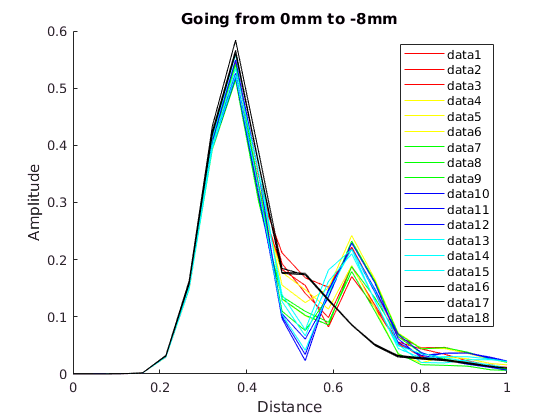

clc
clear variables
close all
addpath('../functions');

% Settings
folder = 'chicken2';
dataType = 'bb';
dacMIN = 0;
dacMAX = 1400;
freq = 3;
global variableName;
variableName = strcat(dataType, num2str(dacMIN), '_', num2str(dacMAX), 'f', num2str(freq));
variableNameRF = strcat('rf', num2str(dacMIN), '_', num2str(dacMAX), 'f', num2str(freq));
x = linspace(0.0, 9.9, 186);
% Load the Radar Data
t = 1;
depths = -50:2:20;
for i = depths
    for j = 1:3
        fileName = strcat(folder, '/', num2str(i), 'mm-', num2str(j), '.mat');
        objdata(t,j) = load(fileName, variableName);
    end
    t = t + 1;
end
% Observe the Radar Data
for j = 1:3
    fileName = strcat(folder, '/baseline-', num2str(j), '.mat');
    baseline(j) = load(fileName, variableName);
end
hold on;
plot(x, abs(objdata(26,1).(variableName)), 'red');
plot(x, abs(objdata(26,2).(variableName)), 'red');
plot(x, abs(objdata(26,3).(variableName)), 'red');
plot(x, abs(objdata(25,1).(variableName)), 'yellow');
plot(x, abs(objdata(25,2).(variableName)), 'yellow');
plot(x, abs(objdata(25,3).(variableName)), 'yellow');
plot(x, abs(objdata(24,1).(variableName)), 'green');
plot(x, abs(objdata(24,2).(variableName)), 'green');
plot(x, abs(objdata(24,3).(variableName)), 'green');
plot(x, abs(objdata(23,1).(variableName)), 'blue');
plot(x, abs(objdata(23,2).(variableName)), 'blue');
plot(x, abs(objdata(23,3).(variableName)), 'blue');
plot(x, abs(objdata(22,1).(variableName)), 'cyan');
plot(x, abs(objdata(22,2).(variableName)), 'cyan');
plot(x, abs(objdata(22,3).(variableName)), 'cyan');
plot(x, abs(baseline(1).(variableName)), 'black');
plot(x, abs(baseline(2).(variableName)), 'black');
plot(x, abs(baseline(3).(variableName)), 'black');
xlim([0, 1]);
title('Going from 0mm to -8mm');
xlabel('Distance');
ylabel('Amplitude');
legend('show')
colorbar off
hold off;

## Average out the radar data

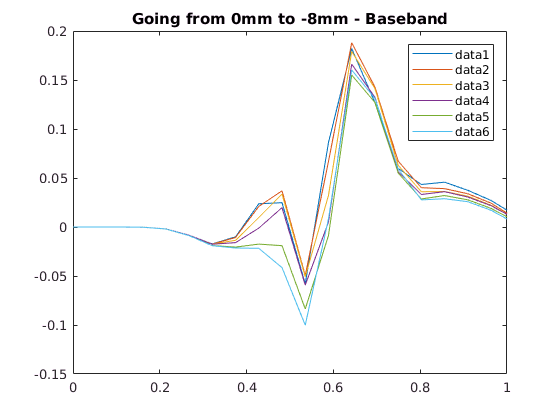

objdataavg = zeros(length(objdata), length(objdata(1, 1).(variableName)));
baselineavg = abs(mean([baseline(1).(variableName); baseline(2).(variableName); baseline(3).(variableName)]));
t = 1;
for i = depths
    objdata1 = abs(objdata(t, 1).(variableName));
    objdata2 = abs(objdata(t, 2).(variableName));
    objdata3 = abs(objdata(t, 3).(variableName));
    objdataavg(t,:) = mean([objdata1; objdata2; objdata3]) - baselineavg;
    t = t + 1;
end

for i = 11:-1:6
   plot(x, objdataavg(i,:)); 
   hold on;
end
xlim([0, 1]);
legend('show');
title('Going from 0mm to -8mm - Baseband');
hold off;

## Mean of the Data

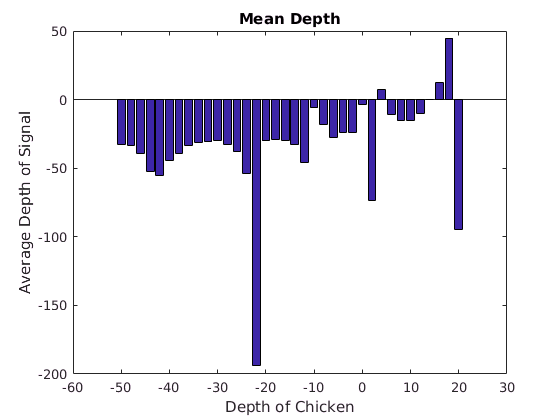

objdataavgmean = objdataavg;
for i = 1:length(depths)
   objdataavgmean(:,i) = objdataavgmean(:,i) .* depths(i);
end
objdataavgmean = mean(objdataavgmean');
total = mean(objdataavg');
bar(depths, objdataavgmean ./ total);
title('Mean Depth')
xlabel('Depth of Chicken')
ylabel('Average Depth of Signal')

## Changes in the the amplitude over time

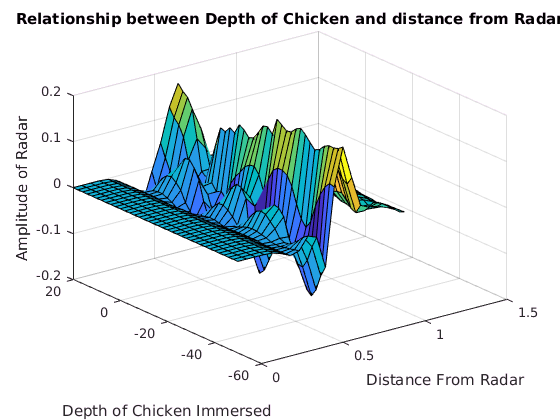

surf(x(1:20), depths, objdataavg(1:end, 1:20));
xlabel('Distance From Radar');
ylabel('Depth of Chicken Immersed');
zlabel('Amplitude of Radar');
title('Relationship between Depth of Chicken and distance from Radar');
hold off;

## Improving the resolution of the resonant chamber using matched filtering

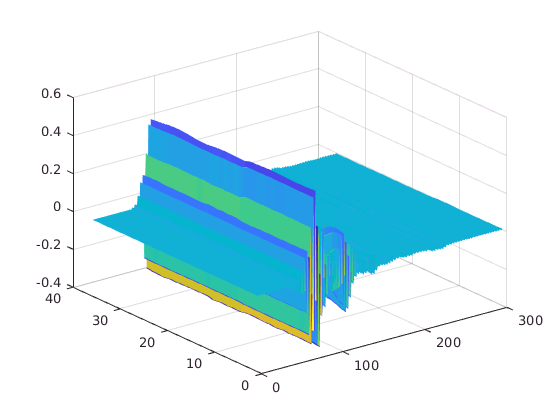

% Load the RF Data
t = 1;
for i = depths
    for j = 1:3
        fileName = strcat(folder, '/', num2str(i), 'mm-', num2str(j), '.mat');
        objdataRF(t,j) = load(fileName, variableNameRF);
    end
    t = t + 1;
end

% Baseline
for j = 1:3
    fileName = strcat(folder, '/baseline-', num2str(j), '.mat');
    baselineRF(j) = load(fileName, variableNameRF);
end
baselineRFavg = abs(mean([baselineRF(1).(variableNameRF); baselineRF(2).(variableNameRF); baselineRF(3).(variableNameRF)]));

% Average and subtract baseline
t = 1;
for i = depths
    objdata1 = (objdataRF(t, 1).(variableNameRF));
    objdata2 = (objdataRF(t, 2).(variableNameRF));
    objdata3 = (objdataRF(t, 3).(variableNameRF));
    objdataRFavg(t,:) = mean([objdata1; objdata2; objdata3]);
    t = t + 1;
end

surf(objdataRFavg(:,1:300), 'LineStyle', 'None');

## Creating an Input Signal

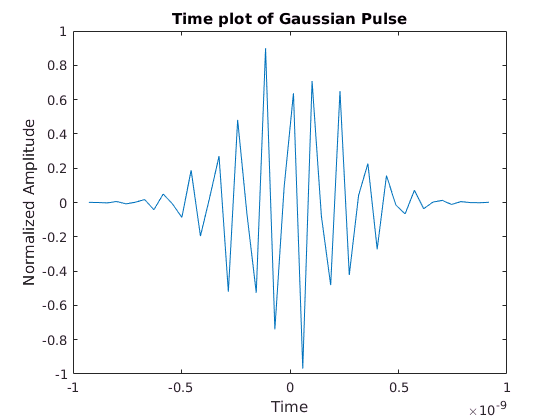

Fs = 23.328e9; % Samples per second
Bw = 1.5e9;

% Using the Xethru Ultra Wideband Pulse
center_freq = 8.748e9;
tc = gauspuls('cutoff',center_freq,Bw/center_freq,[],-60); 
t = -tc : 1/Fs : tc; 
s_tx = gauspuls(t,center_freq,Bw/center_freq); 
figure;
plot(t,s_tx)

title('Time plot of Gaussian Pulse')
xlabel('Time')
ylabel('Normalized Amplitude')

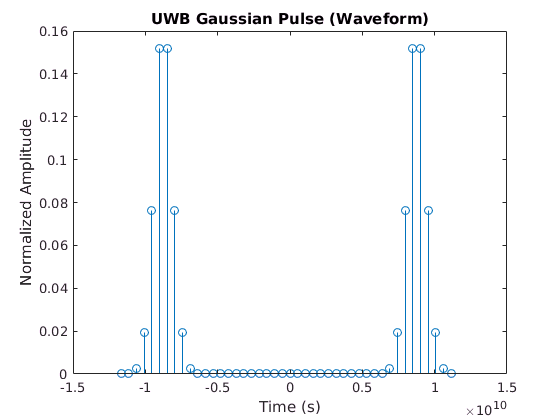


n = length(t);
f = Fs*(-n/2:n/2-1)/n;
S_tx = fftshift(fft(s_tx))/n;
stem(f, abs(S_tx));

title('UWB Gaussian Pulse (Waveform)')
xlabel('Time (s)')
ylabel('Normalized Amplitude')


clear beta fftPulse L P1 P2 pulse tao tc n


## Use the Match and Downconvert method

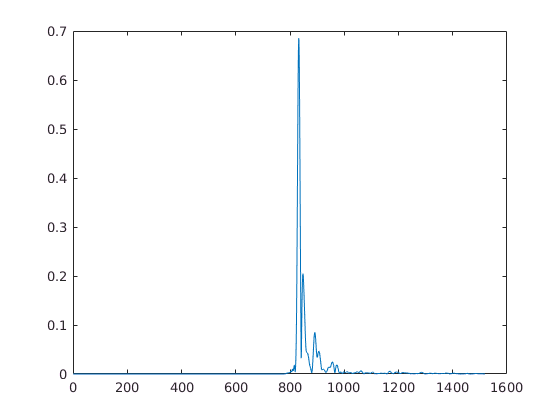

chicken_matched_baseline = match_and_downconvert(s_tx, baselineRFavg, center_freq);

z = 1;
for i = depths
    chicken_matched(z,:) = match_and_downconvert(s_tx, objdataRFavg(z,:), center_freq);
    chicken_matched(z,:) = chicken_matched(z,:) - chicken_matched_baseline;
    z = z + 1;
end 
plot(abs(chicken_matched_baseline));

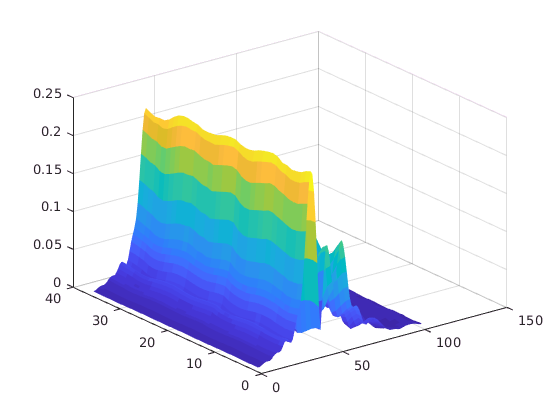

surf(abs(chicken_matched(:,800:900)), 'linestyle', 'none');